# Limb Movement Classification with EMG Data: Statistical Features

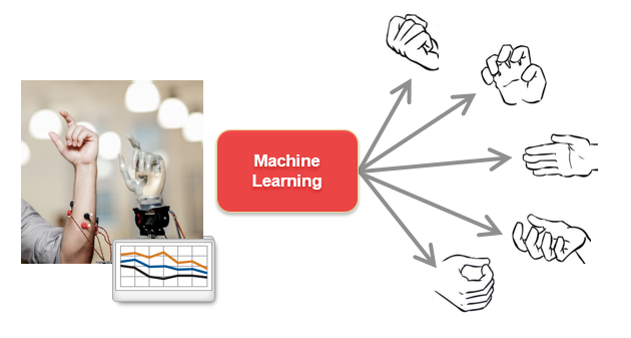

The goal of this analysis is to develop a classifier to identify type of movement from EMG signal for prosthetics development. We will process EMG sensor data with known actions, then train a classification algorithm to make predictions given new sensor readings.  

In this example, we will use basic statistical features as a first pass to see if this satisfies our accuracy requirements.

fs = 1800; % Sensor frequency (Hz)
dt = 1/fs; % Discrete time element (s)

## Import Data

First, we need to import the data from each of the different files into one table. A convenient way to do this is with `datastore`. Datastores allow you to point at a collection of files, specify the formatting, and then read in all or a portion of the data as needed.

trainds = datastore(fullfile('/MATLAB Drive/AI Signals Workshop/EMG/Data/TrainingData/*.csv'));
trainds.SelectedFormats{9} = '%C'; % Convert labels to categorical
nsensors = 8; 
preview(trainds)

ans = 8x9 table
    rawDataOut1    rawDataOut2    rawDataOut3    rawDataOut4    rawDataOut5    rawDataOut6    rawDataOut7    rawDataOut8      Action  
    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    __________

       36838          37549          38656          38854          38616          38933          38893          59486       Chuck Grip
       40395          38024          38854          39723          39644          39763          39684          56561       Chuck Grip
       41344          39091          38893          40118          40395          40158          39723          49407       Chuck Grip
  

Read all of the data into one table and create a time vector for plotting.

TrainData = readall(trainds);
t = seconds(0:dt:dt*(height(TrainData)-1))';

## Visualize Data

Visualize the signals, colored by action, in the grouped scatter plot below.

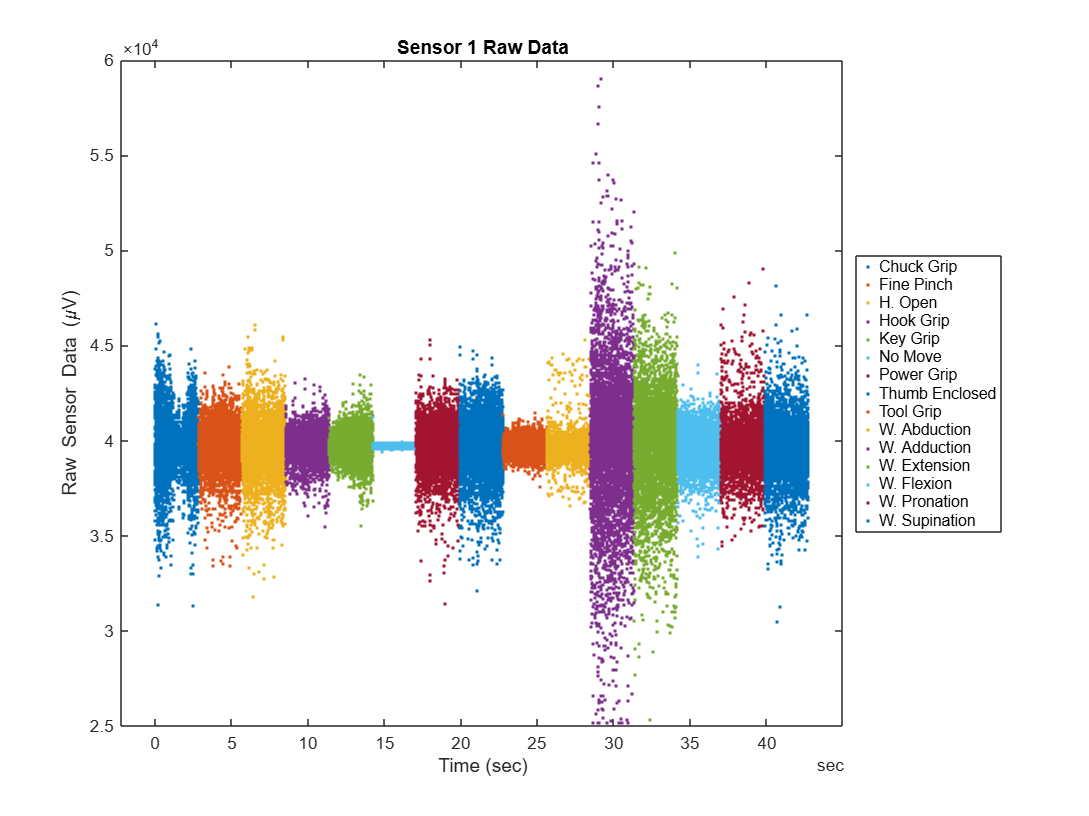

sensorNum = 1;
gscatter(t,TrainData{:,sensorNum},TrainData.Action)
title("Sensor " + num2str(sensorNum) + " Raw Data")
xlabel('Time (sec)')
ylabel('Raw Sensor Data (\muV)')
legend(categories(TrainData.Action),'Location','EastOutside')

We can also take a look at all of the channels for a single action using [`stackedplot`](matlab: web(fullfile(docroot, 'matlab/ref/stackedplot.html'))) and logical indexing.

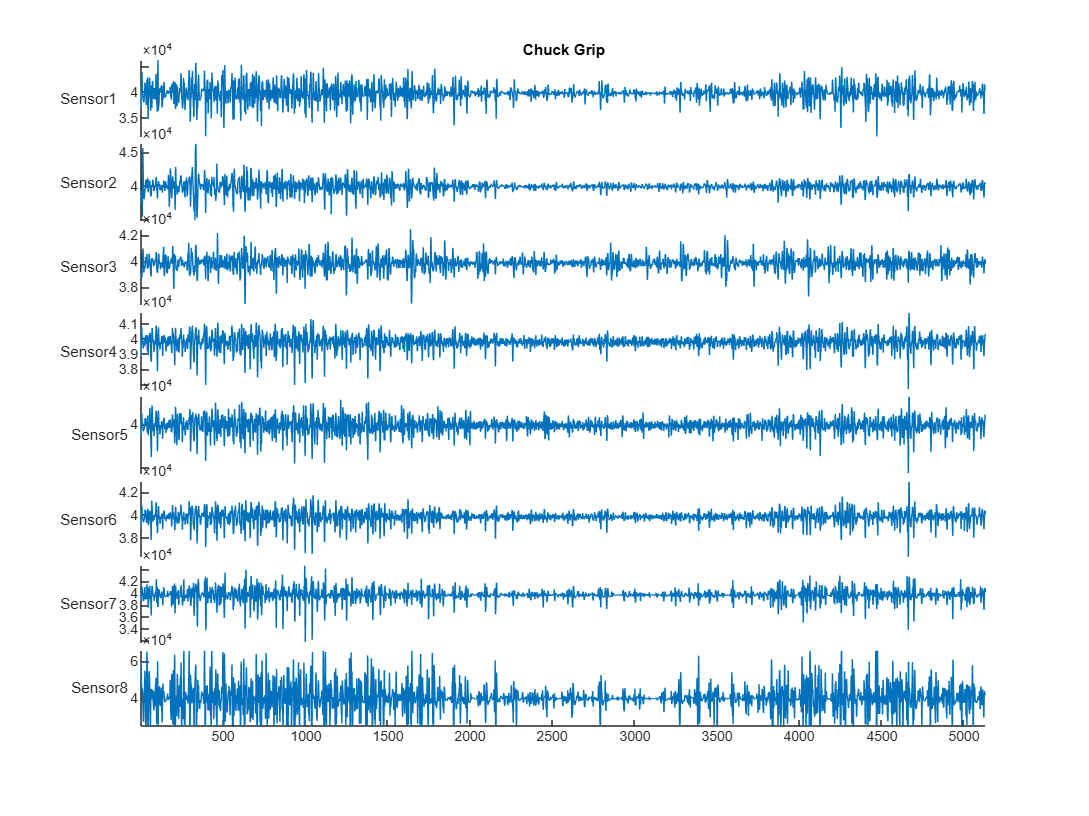

figure
TrainDataTime = table2timetable(TrainData,'RowTimes',t);
actionToPlot = "Chuck Grip";
stackedplot(TrainDataTime{TrainDataTime.Action == actionToPlot, 1:8},'DisplayLabels',"Sensor" + (1:8));
title(num2str(actionToPlot))

## Preprocess Data

Preprocessing can help the classification algorithms do a better job by smoothing, transforming, or applying statistics to the original signal that are better indicators of what is happening in the data. Examining the grouped scatter plot, it appears that the variance, range, and mean of small segments might help differentiate between classes.

We also need to consider the window length when calculating statistics. Rather than using moving statistics, we will take advantage of the fact that the recorded actions require a certain number of samples so all of those adjacent points are part of the same action. To figure out how big this block should be, we will take the greatest common divisor of the number of samples per action and the sampling frequency.

naction = mode(countcats(TrainData.Action)); % Samples in most common action
blocksize = naction/gcd(naction, fs);

## Feature Extraction Using Basic Statistics

Use `blockproc` to apply the functions to the blocks and then append the known action.

% Make functions and intelligent variable names
statfuns = @(x)[max(x) mean(x) min(x) var(x)];
varnames = makeVariableNames({'max';'mean';'min';'var'}, nsensors);

% Apply and append action
TrainDataStats = blockproc(TrainData{:,1:nsensors},[blocksize 1],@(block)statfuns(block.data));
TrainDataStats = array2table(TrainDataStats);
TrainDataStats.Properties.VariableNames = varnames;
TrainDataStats.Action = TrainData.Action(1:blocksize:end);

## Train Classifier

In order to train the classifier, we will use the Classification Learner App. This is an interactive environment where you can experiment with many different machine learning algorithms and evaluate how well they perform.

`classificationLearner`

We can use the generated code from the classification learner to calculate the validation accuracy.  In this case, we use a 25% holdout.

[classifier, validationAccuracy] = trainEMGClassifier(TrainDataStats);
disp(['Accuracy is ', num2str(validationAccuracy * 100) ,'%'])

Accuracy is 95.2522%


## Make Predictions on Test Set

Now that we have a trained classifier, it can be used to make predictions on the independent test set from another experiment.

Apply all of the same preprocessing steps to the new data.

testds = datastore(fullfile('/MATLAB Drive/AI Signals Workshop/EMG/Data/TestingData/*.csv'));
testds.SelectedFormats{9} = '%C';
TestData = readall(testds);
TestDataStats = blockproc(TestData{:,1:nsensors},[blocksize 1],@(block)statfuns(block.data));
TestDataStats = array2table(TestDataStats);
TestDataStats.Properties.VariableNames = varnames;
TestDataStats.Action = TestData.Action(1:blocksize:end);

Then make prediction and compare to known results.

[PredictedAction,score] = predict(classifier.ClassificationEnsemble, TestDataStats);

disp(['Accuracy is ', num2str(nnz(PredictedAction==TestDataStats.Action)./numel(PredictedAction)*100),'%'])

Accuracy is 78.7407%


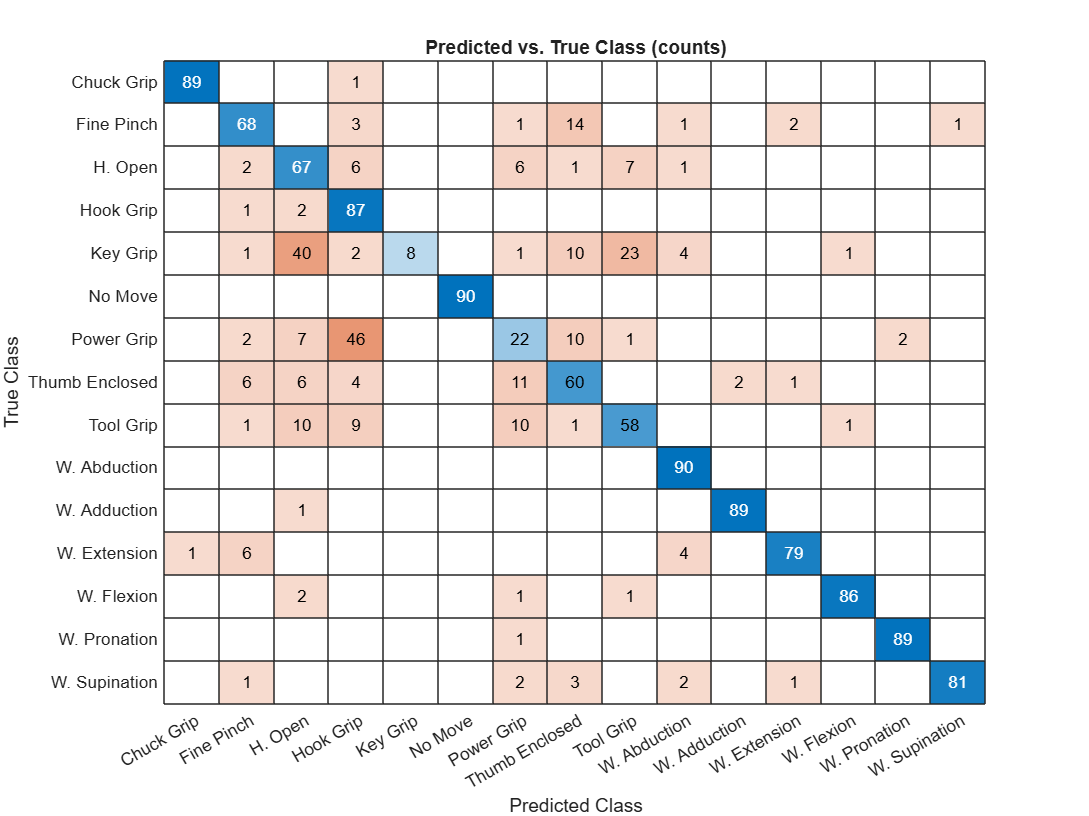

confusionchart(TestDataStats.Action, PredictedAction);
title("Predicted vs. True Class (counts)")

## Can This Be Improved?

The above accuracy leaves a little to be desired. There are numerous things to consider here:

- Did we have the right predictors?

- Are the sensors in the right place?

- Where is the confusion?

- Is there any more information we know that can be used?

If you are doing an action, it is likely that you will be doing this action for a little while. One way to incorporate this knowledge is to look at the score output from the classifier. The score is the probability of the true class matching the predicted class. By averaging the total score over a few predictions we can smooth the predictions to be the most probable one.

actioncats = categories(PredictedAction);
smoothsize = 5;
score3d = reshape(score',numel(actioncats),smoothsize,[]);
scoresum = sum(score3d,2);
[~,idx] = max(scoresum,[],1);
idx = repelem(squeeze(idx),smoothsize,1);
PredictedActionProbability = categorical(actioncats(idx));

disp(['Accuracy is ', num2str(nnz(PredictedActionProbability==TestDataStats.Action)./numel(PredictedActionProbability)*100),'%'])

Accuracy is 87.037%


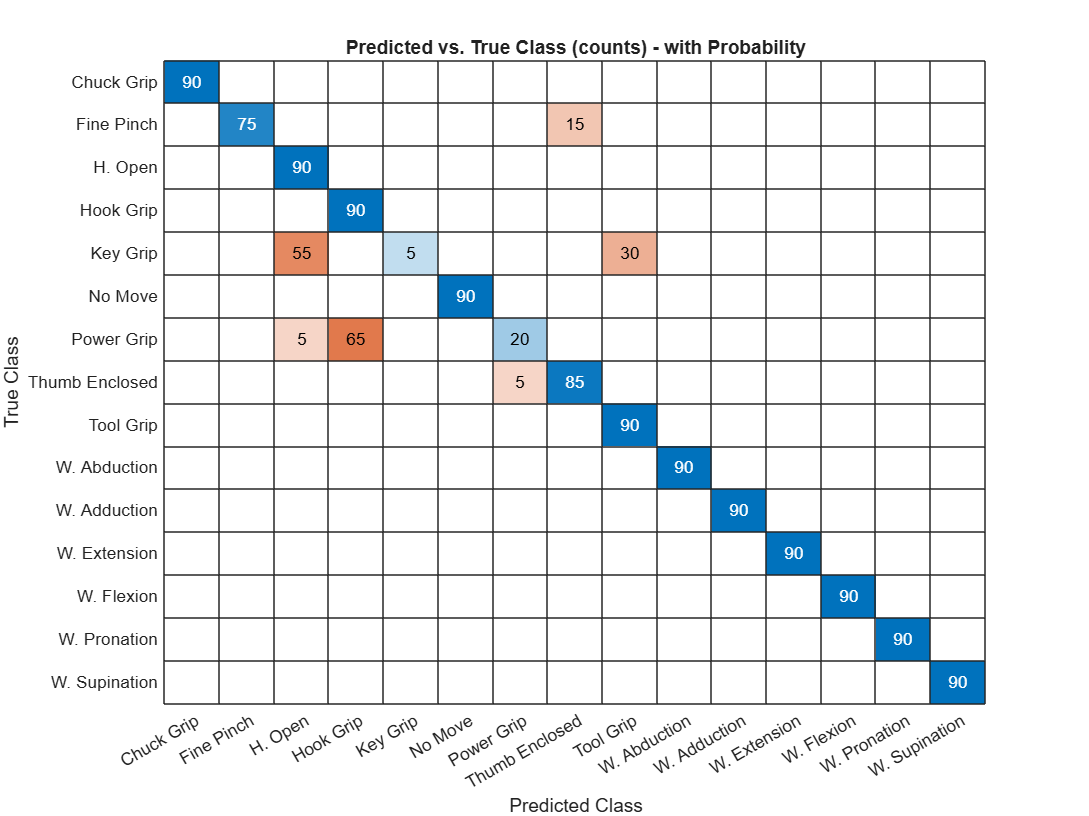

confusionchart(TestDataStats.Action, PredictedActionProbability);
title("Predicted vs. True Class (counts) - with Probability")

## Model Refinement: Number of Trees

How many trees do we really need? The model provides an out-of-bag loss function for calculating how much more error there is by leaving out additional trees.

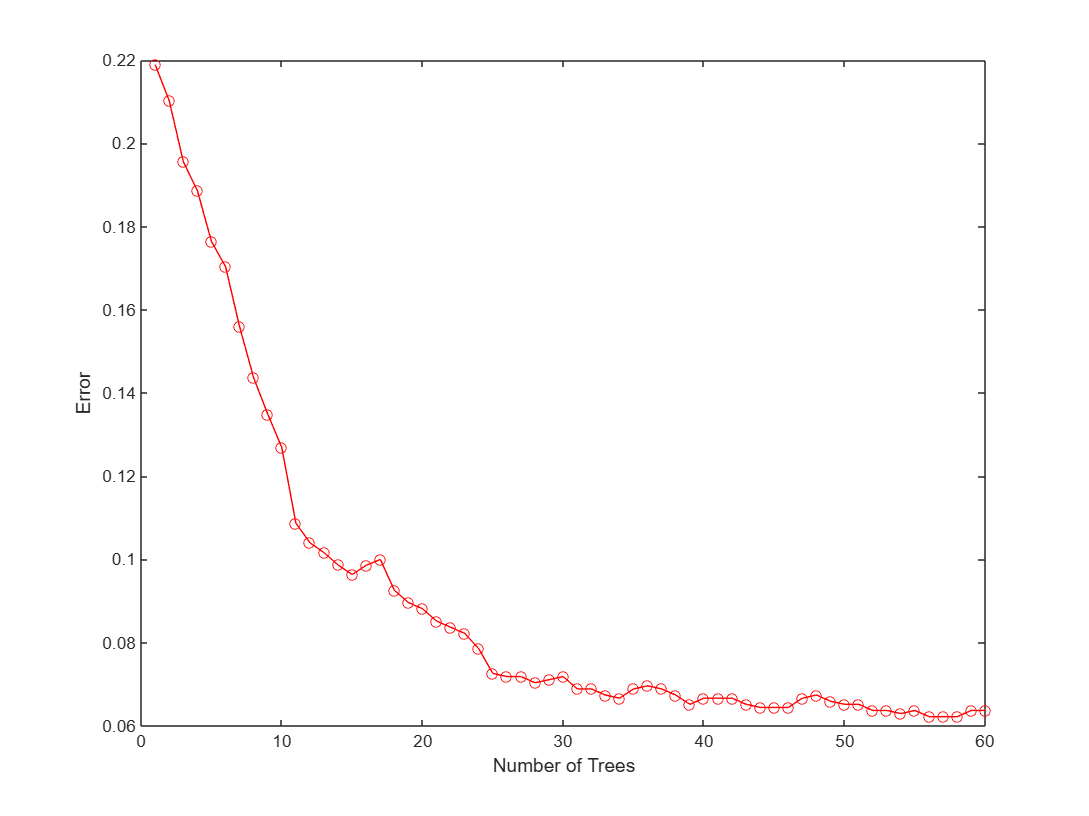

plot(oobLoss(classifier.ClassificationEnsemble,'mode','cumulative'),'ro-')
xlabel('Number of Trees')
ylabel('Error')

## Model Refinement: Predictor Importance

Which predictors are the most important to the model? The `predictorImportance` metric will tell us how much more error there is if that predictor was to be removed.

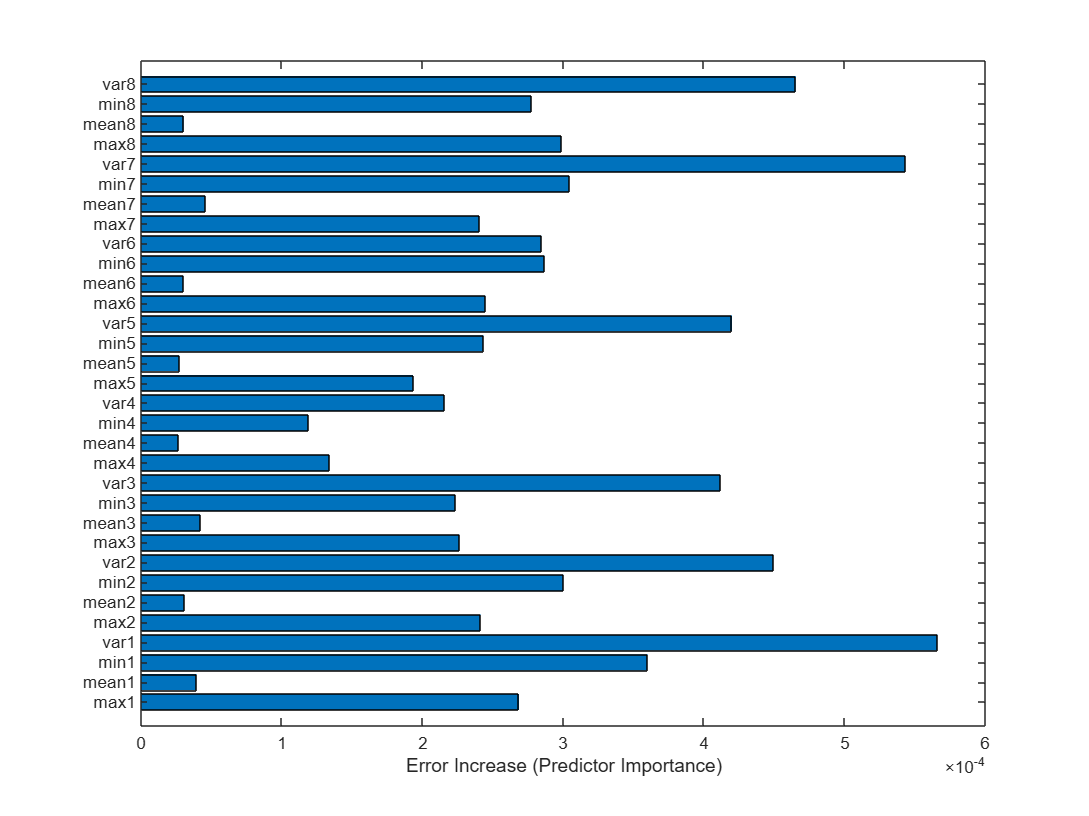

predimp = predictorImportance(classifier.ClassificationEnsemble);
barh(predimp)
ax = gca;
ax.YTick = 1:numel(predimp);
ax.YTickLabel = varnames;
xlabel('Error Increase (Predictor Importance)')

## Model Refinement: Sequential Feature Selection

Finally, one can use [sequential feature selection](matlab: web(fullfile(docroot, 'stats/sequentialfs.html'))) to rigourously test the hypothesis that a predictor is important. This will involve training the model for different combinations of predictors.

`fsnames = selectFeaturesSequentially(TrainDataStats)`

*Copyright 2019 The MathWorks, Inc.*